# How to MATLAB mobile

In this livescript we will summarize the information necessary to use MATLAB mobile for the hackathon.

The bullet points for the smartphone side are:

- Download MATLAB mobile on your smarthphone from the AppStore or PlayStore.

- Login with your MathWorks account (the same as the one you have on your computer)

- Go to Sensors page from the side menu

- Choose the settings you prefer. You can stream to Log (save a file on MATLAB drive) or directly to your computer. Choose the path to save the data. Allow the access to the sensors.

Then on your computer follow this steps:

- Connect MATLAB drive from this button and follow the instructions:  

                                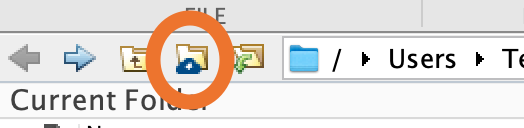

- Navigate to the folder where you saved your sensors data

- Copy the file .mat back to your working folder

### Use MATLAB mobile with live stream.

Run the following comands to get real time data from your device.

Create the object to connect to the smartphone:

m = mobiledev

Mobile devices not detected. Make sure you enable sensor access on the device by selecting 'Sensors > More > Sensor Access' in MATLAB
Mobile.

if this is not working check if your computer and smartphone are connected under the same Wi-Fi.

To start logging elements run:

m.Logging = 1

acc =     0.0736   -0.1013    9.8468
    0.0555   -0.1109    9.8096
    0.0292   -0.1418    9.8064
    0.0192   -0.1382    9.8139
    0.0022   -0.1302    9.8173
   -0.0434   -0.1284    9.7542
    0.0141   -0.1319    9.8254
   -2.2751   -0.7643    9.8259
    1.2448    0.2331    9.7968
   -1.8642   -1.3143    9.8000


time_acc =          0
    0.1010
    0.2010
    0.3020
    0.4020
    0.5030
    0.6030
    0.7040
    0.8040
    0.9050


Run the folloging comands to save the data 

[acc , time_acc] = m.accellog

ang =    -0.0001    0.0038   -0.0036
   -0.0020    0.0066   -0.0047
    0.0020    0.0037   -0.0011
    0.0007    0.0078   -0.0044
    0.0012    0.0039   -0.0036
   -0.0047    0.0131   -0.0017
    0.0001    0.0049   -0.0040
    0.0013   -0.0037    1.0958
   -0.0020   -0.0014   -0.0005
    0.0127   -0.0336    2.9615


time_ang =          0
    0.1010
    0.2010
    0.3020
    0.4020
    0.5030
    0.6030
    0.7040
    0.8040
    0.9050


[ang, time_ang] = m.angvellog

magnetic =     9.7335   21.5805  -29.8934
    9.8561   21.3807  -29.7962
    9.8508   21.4151  -29.6336
    9.9108   21.4923  -29.7052
    9.7421   21.4274  -29.7575
    9.7985   21.5095  -29.7796
    9.7584   21.4899  -29.8106
   10.2831   21.1392  -29.9547
   11.1890   20.3562  -29.7723
   13.2791   18.2483  -30.9365


time_magnetic =     0.0060
    0.1070
    0.2070
    0.3080
    0.4080
    0.5090
    0.6090
    0.7100
    0.8100
    0.9110


[magnetic, time_magnetic] = m.magfieldlog

orientation =   -89.7323    0.6421   -0.0762
  -89.7333    0.6432   -0.0767
  -89.7321    0.6429   -0.0787
  -89.7329    0.6413   -0.0771
  -89.7331    0.6412   -0.0762
  -89.7347    0.6480   -0.0759
  -89.7390    0.6486   -0.1256
  -91.7006    0.6396   -0.1958
  -95.0823    0.6506   -0.1394
 -104.5302    0.6313   -0.2200


time_orientation =     0.0060
    0.1070
    0.2070
    0.3080
    0.4080
    0.5090
    0.6090
    0.7100
    0.8100
    0.9110


[orientation, time_orientation] = m.orientlog



lat =

     []


long =

     []


tp =

     []


speed =

     []


course =

     []


alt =

     []



[lat, long, tp, speed, course, alt] = m.poslog